x = [7.2, 5.4, 3.6, 1.8];
x = x/2;
y = sqrt(25-x.^2);

angles = atan(x./y)*180/pi;
theta = [-angles, 0, flip(angles)]';


WHITE_10_Angles_Scaled = scale(WHITE_10_Angles);
WHITE_100_Angles_Scaled = scale(WHITE_100_Angles);
W_10 = reshape(cell2mat(WHITE_10_Angles_Scaled(:,3)),9,15);
W_100 = reshape(cell2mat(WHITE_100_Angles_Scaled(:,3)),9,15);
W_10_normaliseW_AS = W_10(:,1:9)./W_10(5,1:9);
W_100_normaliseW_AS = W_100(:,1:9)./W_100(5,1:9);

% scatter(theta, W_10_normaliseW_AS(:,1))
% hold off
W_10_normaliseW_VEML = W_10(:,11:14)./W_10(5,11:14);
W_100_normaliseW_VEML = W_100(:,11:14)./W_100(5,11:14);
% scatter(theta, W_10(:,9))
% scatter(theta, W_100(:,9))
i = 9

i = 9

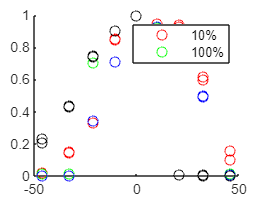

scatter(theta, W_10_normaliseW_AS(:,[7, 4, 2, 9]),[],VEML_Colours)
hold on
scatter(theta, W_100_normaliseW_AS(:,[7, 4, 2, 9]),[],VEML_Colours)
legend("10%", "100%")
hold off

% i = 8
% scatter(theta, W_10_normaliseW_AS(:,i))
% hold on
% scatter(theta, W_100_normaliseW_AS(:,i))
% legend("10%", "100%")
% hold off
% i = 7
% scatter(theta, W_10_normaliseW_AS(:,i))
% hold on
% scatter(theta, W_100_normaliseW_AS(:,i))
% legend("10%", "100%")
% hold off
% i = 6
% scatter(theta, W_10_normaliseW_AS(:,i))
% hold on
% scatter(theta, W_100_normaliseW_AS(:,i))
% legend("10%", "100%")
% hold off
% i = 5
% scatter(theta, W_10_normaliseW_AS(:,i))
% hold on
% scatter(theta, W_100_normaliseW_AS(:,i))
% legend("10%", "100%")
% hold off
% i = 4
% scatter(theta, W_10_normaliseW_AS(:,i))
% hold on
% scatter(theta, W_100_normaliseW_AS(:,i))
% legend("10%", "100%")
% hold off
% i = 3
% scatter(theta, W_10_normaliseW_AS(:,i))
% hold on
% scatter(theta, W_100_normaliseW_AS(:,i))
% legend("10%", "100%")
% hold off
% i = 2
% scatter(theta, W_10_normaliseW_AS(:,i))
% hold on
% scatter(theta, W_100_normaliseW_AS(:,i))
% legend("10%", "100%")
% hold off
% i = 1
% scatter(theta, W_10_normaliseW_AS(:,i))
% hold on
% scatter(theta, W_100_normaliseW_AS(:,i))
% legend("10%", "100%")
% hold off


i = 4

i = 4

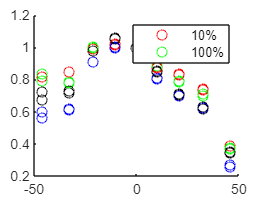

scatter(theta, W_10_normaliseW_VEML(:,1:4),[],VEML_Colours)
hold on
scatter(theta, W_100_normaliseW_VEML(:,1:4),[],VEML_Colours)
legend("10%", "100%")
hold off

% i = 3
% scatter(theta, W_10_normaliseW_VEML(:,i))
% hold on
% scatter(theta, W_100_normaliseW_VEML(:,i))
% legend("10%", "100%")
% hold off
% i = 2
% scatter(theta, W_10_normaliseW_VEML(:,i))
% hold on
% scatter(theta, W_100_normaliseW_VEML(:,i))
% legend("10%", "100%")
% hold off
% i = 1
% scatter(theta, W_10_normaliseW_VEML(:,i))
% hold on
% scatter(theta, W_100_normaliseW_VEML(:,i))
% legend("10%", "100%")
% hold off

function COLOUR_Scaled = scale(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(9,4);
    for j = 1:9
        for i = 1:4
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end

function COLOUR_Scaled = scale2(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(14,4);
    for j = 1:14
        for i = 1:4
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end